# Scientific Programming, Worksheet 4, Ex. 6

*Written by: Kundyz Muktar, Course: Scientific Programming (2025), MATLAB version: R2023a*

clear; clc; close all;

## Part A: Polynomial test: f(x,y) = x^j y^k

j = 2;
k = 1;
n = 6;  

f_a = @(x,y) x.^j .* y.^k;
q_approx_a = DuffyQuadratureTref(0, 1, 0, 1, f_a, n, n);
q_exact_a = f_exact_b(j,k);


fprintf('===== (a) Polynomial Test =====\n');

===== (a) Polynomial Test =====


fprintf('f(x,y) = x^%d y^%d\n', j, k);

f(x,y) = x^2 y^1


fprintf('Using n = %d => Qapprox = %.12f\n', n, q_approx_a);

Using n = 6 => Qapprox = 0.013888888889


fprintf('Exact integral         = %.12f\n', q_exact_a);

Exact integral         = 0.016666666667


fprintf('Absolute error         = %.2e\n\n', abs(q_approx_a - q_exact_a));

Absolute error         = 2.78e-03



## Part B: Test with f(x,y) = sin(2π(x + y))


f_b = @(x,y) sin(2*pi*(x + y));
q_exact_b = -0.15915494309189533577;

n_values = 1:8;
err = zeros(size(n_values));

for idx = 1:length(n_values)
    nTest = n_values(idx);

    q_approx_b = DuffyQuadratureTref(0, 1, 0, 1, f_b, nTest, nTest);
    err(idx) = abs(q_approx_b - q_exact_b);
end

fprintf('===== (b) Sin(2π(x+y)) Test =====\n');

===== (b) Sin(2π(x+y)) Test =====


disp('   n        Qapprox           Error');

   n        Qapprox           Error


for idx = 1:length(n_values)
    fprintf('%4d   % .12f   % .2e\n', ...
        n_values(idx), ...
        DuffyQuadratureTref(0,1,0,1,f_b,n_values(idx),n_values(idx)), ...
        err(idx));
end

   1    0.000000000000    1.59e-01
   2   -0.000000000000    1.59e-01
   3   -0.222222222222    6.31e-02
   4   -0.187152000974    2.80e-02
   5   -0.154713176774    4.44e-03
   6   -0.156725640187    2.43e-03
   7   -0.159378507276    2.24e-04
   8   -0.159289260878    1.34e-04


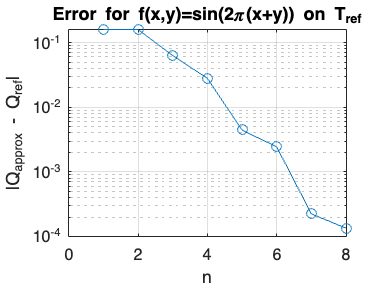


figure;
semilogy(n_values, err, 'o-');
grid on;
xlabel('n');
ylabel('|Q_{approx} - Q_{ref}|');
title('Error for f(x,y)=sin(2\pi(x+y)) on T_{ref}');

function val = f_exact_b(j,k)
    val = (1/(k+1)) * factorial(j) * factorial(k+1) / factorial(j+k+2);
end


*Taken from Worksheet 4, Ex 5:*


function Q = DuffyQuadratureTref(a, b, c, d, f, nx, ny)

    [x, wX] = quadrature(a, b, nx); % x direction
    [y, wY] = quadrature(c, d, ny); % y direction
 
    Q = 0;
    for i = 1:nx
        for j = 1:ny
            Q = Q + wX(i) * wY(j) * (1-x(j)) *   f(  x(i), (1-x(i))*x(j)   );
        end
    end
end



*Taken from Worksheet 3, Ex 3:*

function [x, w] = quadrature(a, b, n)
    if n == 1
        x = a;  % if only one node, choose the left endpoint (could also choose the midpoint)
        w = (b-a);
        return
    end

    h = (b - a) / (n - 1);  % quadrature step size
    x = a:h:b;
    

    x01 = linspace(0, 1, n); 
    w01 = quadratureWeights(x01);
    w = (b - a) * w01;
end

%% from ex 1 or 2
function w = quadratureWeights(x)
    n = numel(x);
    A = zeros(n,n);
    b = zeros(n,1);

    for row = 0:n-1
        A(row+1,:) = x.^row;
        b(row+1)   = 1/(row+1);
    end

    w = A\b;
end
%% from ex 1
function [A, b_vals] = build_A_b(k, N, x_vals)
    % Here k is the maximum polynomial degree (so there are k+1 moments)
    A = zeros(k+1, N);
    b_vals = zeros(k+1, 1);
    for row = 0:k
        A(row+1, :) = x_vals.^row;
        b_vals(row+1) = 1/(row+1);
    end
end

